Data

RequiredMaps = 100000

load("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\DL\AllSolvedData" + RequiredMaps + ".mat", 'AllSolvedData')
head(AllSolvedData)
Database = AllSolvedData;
statespace = stateSpaceSE2;
statespace.StateBounds = [[0 20]; [0 20]; [-3.1416 3.1416]];



figure
for i=1:4
    subplot(2,2,i)    
    ind = randi(height(Database)); % Select a random sample
    map = Database(ind,:).Var1; % Get map from Map column of the table
    pathStates = Database(ind,:).Var2{1}; % Get path from Path column of the table
    start = pathStates(1,:); 
    goal = pathStates(end,:);
    
    % Plot the data
    show(map); 
    hold on
    plot(pathStates(:,1),pathStates(:,2),plannerLineSpec.path{:})
    plot(start(1),start(2),plannerLineSpec.start{:})
    plot(goal(1),goal(2),plannerLineSpec.goal{:})
    title("")
end
legend

mpnet = mpnetSE2;
mpnet.LossWeights = [100 100 0];
mpnet.EncodingSize = [9 9];

split = 0.8;

trainData = Database(1:int32(split*end),:)
validationData = Database(int32(split*end)+1:end,:)

dsTrain = mpnetPrepareData(trainData,mpnet);
dsValidation = mpnetPrepareData(validationData,mpnet);

preparedDataSample = read(dsValidation);
preparedDataSample(1,:)

options = trainingOptions("adam",...
        MiniBatchSize=2048,...
        MaxEpochs=50,...
        Shuffle="every-epoch",...
        ValidationData=dsValidation,...
        ValidationFrequency=2000,...
        Plots="training-progress");

    % Train network
[net, info] = trainnet(dsTrain, mpnet.Network, @mpnet.loss, options);
    
    % Update Network property of mpnet object with net
mpnet.Network = net;


mpnet
save("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\DL\mpnet.mat", "mpnet")

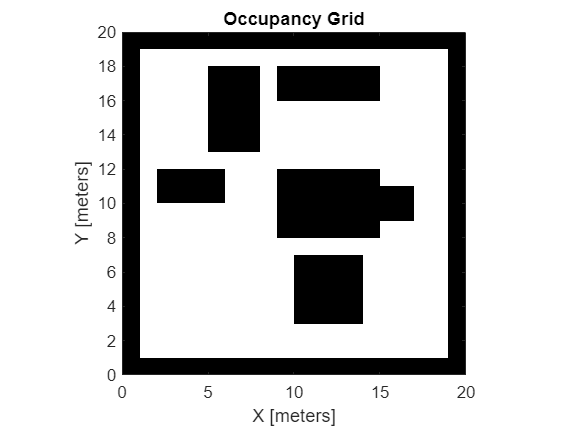



stateSamplerDL = stateSamplerMPNET(statespace,mpnet);

ind = randi(height(validationData));
map = validationData(ind,:).Var1;
start = double(validationData(ind,:).Var2{1,:}(1,:));
goal = double(validationData(ind,:).Var2{1,:}(end,:));

show(map)


stateSamplerDL.Environment = map;
stateSamplerDL.StartState = start;
stateSamplerDL.GoalState = goal;
stateSamplerDL

stateSamplerDL =   stateSamplerMPNET with properties:

               StateSpace: [1×1 stateSpaceSE2]
    MotionPlanningNetwork: [1×1 mpnetSE2]
              Environment: [1×1 occupancyMap]
               StartState: [14 15 0]
                GoalState: [6 5 0]
        MaxLearnedSamples: 50
            GoalThreshold: 1


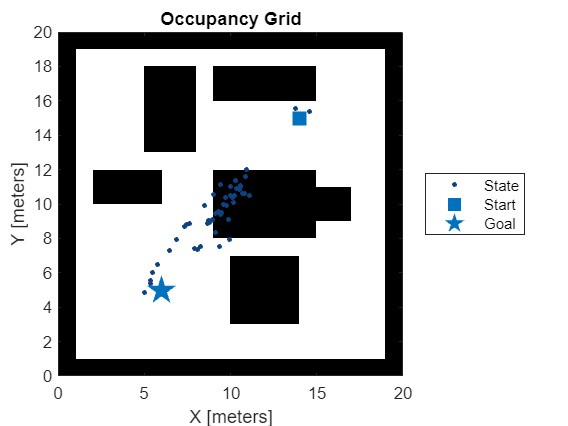

numSamples =50;
stateSamplerDL.MaxLearnedSamples = 50;
samples = sample(stateSamplerDL, numSamples);
figure
show(map);
hold on;
plot(samples(:,1),samples(:,2),plannerLineSpec.state{:})
plot(start(1),start(2),plannerLineSpec.start{:});
plot(goal(1),goal(2),plannerLineSpec.goal{:});
legend(Location="eastoutside")

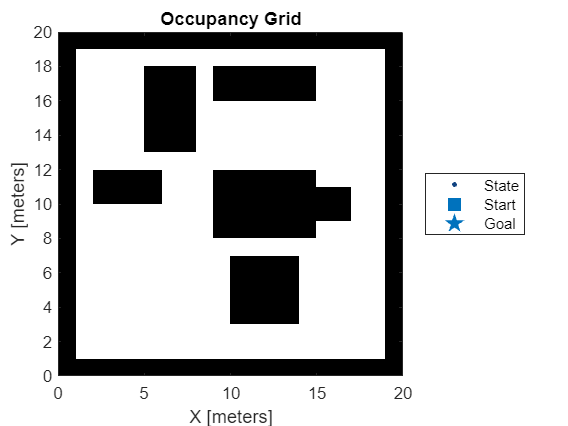

stateValidator = validatorOccupancyMap(statespace,Map=map);
stateValidator.ValidationDistance = 0.1;
show(map)

stateValidator

stateValidator =   validatorOccupancyMap with properties:

                   Map: [1×1 occupancyMap]
            StateSpace: [1×1 stateSpaceSE2]
             XYIndices: [1 2]
    ValidationDistance: 0.1000


start

start =     14    15     0


goal

goal =      6     5     0


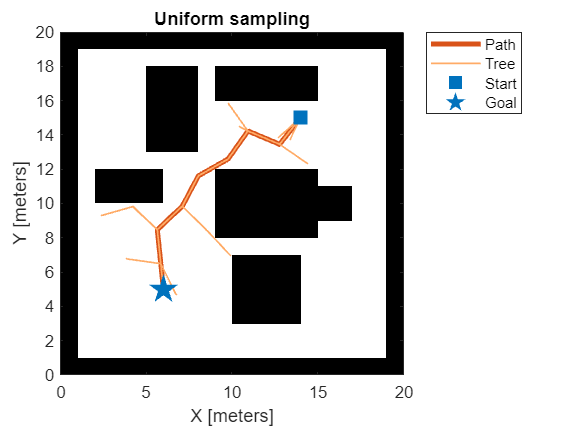


% Create RRT* planner with default uniform sampler
plannerUniformSampling = plannerRRTStar(statespace,stateValidator,MaxConnectionDistance=2,StateSampler=stateSamplerUniform(statespace));
[pathUniformSampling,solutionInfoUniformSampling] = plan(plannerUniformSampling,start,goal);

% Visualize results for uniform sampling
figure
show(map)
hold on;
plot(pathUniformSampling.States(:,1),pathUniformSampling.States(:,2),plannerLineSpec.path{:})
plot(solutionInfoUniformSampling.TreeData(:,1),solutionInfoUniformSampling.TreeData(:,2),plannerLineSpec.tree{:})
plot(start(1),start(2),plannerLineSpec.start{:});
plot(goal(1),goal(2),plannerLineSpec.goal{:});
legend(Location="northeastoutside")
title("Uniform sampling")

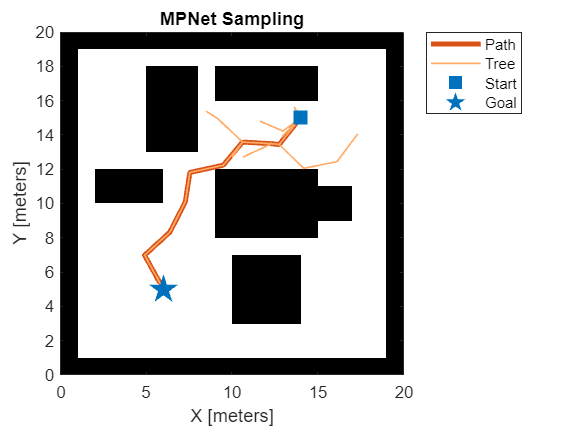

plannerDLSampling = plannerRRTStar(statespace,stateValidator,MaxConnectionDistance=2,StateSampler=stateSamplerDL);
[pathDLSampling,solutionInfoDLSampling] = plan(plannerDLSampling,start,goal);

% Visualize results with deep learning based sampling
figure
show(map);
hold on;
plot(pathDLSampling.States(:,1),pathDLSampling.States(:,2),plannerLineSpec.path{:})
plot(solutionInfoDLSampling.TreeData(:,1),solutionInfoDLSampling.TreeData(:,2),plannerLineSpec.tree{:})
plot(start(1),start(2),plannerLineSpec.start{:})
plot(goal(1),goal(2),plannerLineSpec.goal{:})
legend(Location="northeastoutside")
title("MPNet Sampling")


pathDLSampling.States

ans =    14.0000   15.0000         0
   12.7506   13.4383         0
   12.3167   13.4859    1.4826
   10.6138   13.5830   -2.3562
    9.4923   12.2340   -2.3562
    7.5407   11.8087   -2.6731
    7.2814   10.1108   -2.5580
    6.3774    8.3278   -2.3670
    4.9019    6.9842   -2.7856
    5.8046    5.3530   -0.4956


% Number of runs to benchmark the planner
runCount = 30;

% Create plannerBenchmark object
pb = plannerBenchmark(stateValidator,start,goal);

% Create function handles to create planners for uniform sampling and deep
% learning-based sampling
plannerUniformSamplingFcn = @(stateValidator)plannerRRTStar(stateValidator.StateSpace,stateValidator,MaxConnectionDistance=10);
plannerMPNetSamplingFcn = @(stateValidator)plannerRRTStar(stateValidator.StateSpace,stateValidator,MaxConnectionDistance=10,StateSampler=stateSamplerDL);

% Create plan function
plnFcn = @(initOut,s,g)plan(initOut,s,g);

% Added both planners to plannerBenchmark object
addPlanner(pb,plnFcn,plannerUniformSamplingFcn,PlannerName="Uniform");
addPlanner(pb,plnFcn,plannerMPNetSamplingFcn,PlannerName="MPNet");

% Run planners for specified runCount
runPlanner(pb,runCount)

Initializing Uniform ...
Done.
Planning a path from the start pose (14 15 0) to the goal pose (6 5 0) using Uniform.
Executing run 1.
Executing run 2.
Executing run 3.
Executing run 4.
Executing run 5.
Executing run 6.
Executing run 7.
Executing run 8.
Executing run 9.
Executing run 10.
Executing run 11.
Executing run 12.
Executing run 13.
Executing run 14.
Executing run 15.
Executing run 16.
Executing run 17.
Executing run 18.
Executing run 19.
Executing run 20.
Executing run 21.
Executing run 22.
Executing run 23.
Executing run 24.
Executing run 25.
Executing run 26.
Executing run 27.
Executing run 28.
Executing run 29.
Executing run 30.
Initializing MPNet ...
Done.
Planning a path from the start pose (14 15 0) to the goal pose (6 5 0) using MPNet.
Executing run 1.
Executing run 2.
Executing run 3.
Executing run 4.
Executing run 5.
Executing run 6.
Executing run 7.
Executing run 8.
Executing run 9.
Executing run 10.
Executing run 11.
Executing run 12.
Executing run 13.
Executing run 

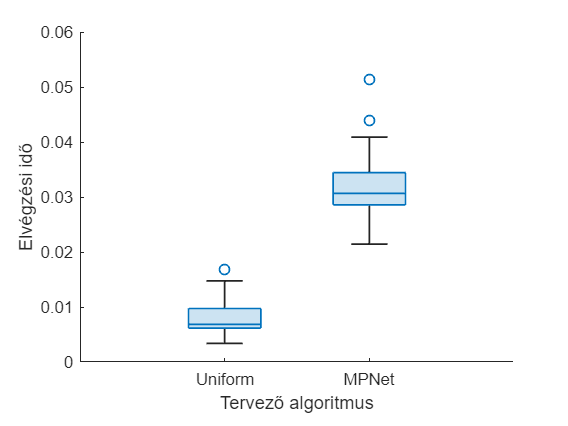

figure
show(pb,"executionTime")
xlabel("Tervező algoritmus")
ylabel("Elvégzési idő")

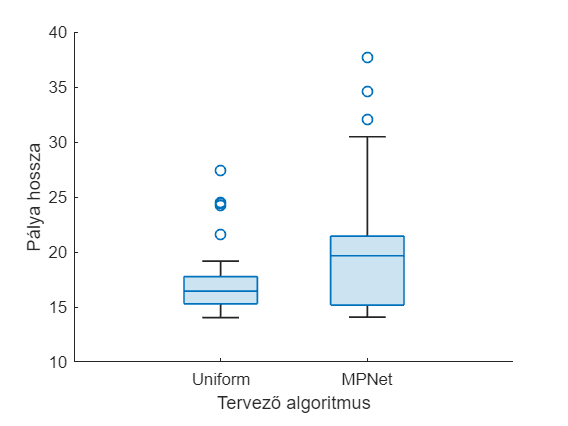

figure
show(pb,"pathLength")
xlabel("Tervező algoritmus")
ylabel("Pálya hossza")

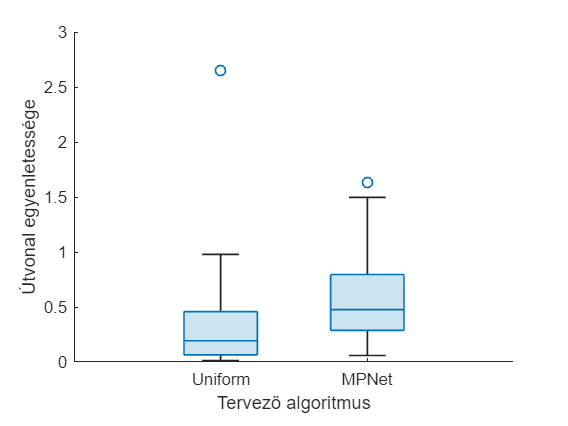

figure
show(pb,"smoothness")
xlabel("Tervező algoritmus")
ylabel("Útvonal egyenletessége")